clc;clear;close all;
addpath("lib\");
format long;

% Mainbody
mass_of_Mainbody = 1414.04421338;  % 질량 (g)
center_of_mass_MainBody = [18.19659659; -0.24888409; 35.42269696];  % 무게 중심 위치 (mm)
inertia_tensor_MainBody = [4191453.72496564, 19611.02661734, 183001.27422549;
                           19611.02661734, 6619178.75424983, 6399.95018693;
                           183001.27422549, 6399.95018693, 7735669.49472275];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Calf Link Left
mass_of_Calf_Link_Left = 338.23782393;  % 질량 (g)
center_of_mass_Calf_Link_Left = [169.71073180; -3.92577446; 7.13663078];  % 무게 중심 위치 (mm)
inertia_tensor_Calf_Link_Left = [108187.53374990, -5688.74489609, -34349.39868930;
                                  -5688.74489609, 849624.61514512, -272.20346797;
                                  -34349.39868930, -272.20346797, 820318.28517488];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Calf Link Right
mass_of_Calf_Link_Right = 338.23782393;  % 질량 (g)
center_of_mass_Calf_Link_Right = [169.71091698; 3.92574726; 7.13537305];  % 무게 중심 위치 (mm)
inertia_tensor_Calf_Link_Right = [108187.86830599, 5689.13762061, -34348.43584610;
                                   5689.13762061, 849621.31645905, 266.26892472;
                                   -34348.43584610, 266.26892472, 820314.86080829];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Thigh Link Active Left
mass_of_ThighLink_Active_Left = 42.41994494;  % 질량 (g)
center_of_mass_ThighLink_Active_Left = [-48.46903323; 4.61143087; 2.04282631];  % 무게 중심 위치 (mm)
inertia_tensor_ThighLink_Active_Left = [5006.89568398, 6444.24555368, -846.35023128;
                                         6444.24555368, 48849.83835373, 404.38523501;
                                         -846.35023128, 404.38523501, 49929.39396428];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Thigh Link Active Right
mass_of_ThighLink_Active_Right = 42.41994494;  % 질량 (g)
center_of_mass_ThighLink_Active_Right = [-48.46902377; -4.61143086; 2.04281842];  % 무게 중심 위치 (mm)
inertia_tensor_ThighLink_Active_Right = [5006.89699630, -6444.24742526, -846.35096499;
                                          -6444.24742526, 48849.85593152, -404.38374370;
                                          -846.35096499, -404.38374370, 49929.41023364];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Thigh Link Passive Left
mass_of_ThighLink_Passive_Left = 39.26139565;  % 질량 (g)
center_of_mass_ThighLink_Passive_Left = [-77.21916722; 10.27201342; -3.86042407];  % 무게 중심 위치 (mm)
inertia_tensor_ThighLink_Passive_Left = [5253.53554832, 5957.24686321, 2247.31583435;
                                          5957.24686321, 60185.49451452, -799.05607096;
                                          2247.31583435, -799.05607096, 60398.22510949];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Thigh Link Passive Right
mass_of_ThighLink_Passive_Right = 39.26139565;  % 질량 (g)
center_of_mass_ThighLink_Passive_Right = [-77.21916722; -10.27201342; -3.86042407];  % 무게 중심 위치 (mm)
inertia_tensor_ThighLink_Passive_Right = [5253.53554222, -5957.24686336, 2247.31583389;
                                           -5957.24686336, 60185.49451538, 799.05607092;
                                           2247.31583389, 799.05607092, 60398.22511646];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Wheel
mass_of_Wheel = 237.11770281;  % 질량 (g)
center_of_mass_Wheel = [-0.00000687; 0.43740164; -0.00000028];  % 무게 중심 위치 (mm)
inertia_tensor_Wheel = [377169.50236306, -0.00684531, -0.00114686;
                         -0.00684531, 723999.02807526, 0.00006205;
                         -0.00114686, 0.00006205, 377169.52206100];  % 무게 중심 기준 관성 모멘트 (g mm^2)

% Wheel Right
mass_of_Wheel_Right = 214.11770281;  % 질량 (g)
center_of_mass_Wheel_Right = [-0.00000761; 0.48438625; -0.00000031];  % 무게 중심 위치 (mm)
inertia_tensor_Wheel_Right = [334104.60295742, -0.00692262, -0.00045120;
                               -0.00692262, 640742.79507983, 0.00005987;
                               -0.00045120, 0.00005987, 334104.65585037];  % 무게 중심 기준 관성 모멘트 (g mm^2)


% link_parameter
properties.a = 75 * cos(pi/6) * 1e-3;
properties.b = 75 * sin(pi/6) * 1e-3;
properties.l1 = 106 * 1e-3;
properties.l2 = 77 * 1e-3;
properties.l3 = 50 * 1e-3;
properties.l4 = 137 * 1e-3;
properties.l5 = 8 * 1e-3;

% wheel width
properties.L = 123 * 1e-3;
properties.R = 76.2 * 1e-3;


% 각 link들의 CoM Offset (순서: [Body, TAR, TAL, TPR, TPL, CR, CL])
properties.c_vectors = [
    center_of_mass_MainBody, ...
    center_of_mass_ThighLink_Active_Right, ...
    center_of_mass_ThighLink_Active_Left, ...
    center_of_mass_ThighLink_Passive_Right, ...
    center_of_mass_ThighLink_Passive_Left, ...
    center_of_mass_Calf_Link_Right, ...
    center_of_mass_Calf_Link_Left
    ];
properties.c_vectors = properties.c_vectors * 1e-3;

% 각 link들의 질량 (순서: [Body, TAR, TAL, TPR, TPL, CR, CL])
properties.masses = [
    mass_of_Mainbody, ...
    mass_of_ThighLink_Active_Right, ...
    mass_of_ThighLink_Active_Left, ...
    mass_of_ThighLink_Passive_Right, ...
    mass_of_ThighLink_Passive_Left, ...
    mass_of_Calf_Link_Right, ...
    mass_of_Calf_Link_Left
    ];
properties.masses = properties.masses * 1e-3;

% 각 link들의 CoM 기준 관성 모멘트 텐서 (순서: [Body, TAR, TAL, TPR, TPL, CR, CL])
properties.IG_matrices(:,:,1) = inertia_tensor_MainBody * 1e-9;
properties.IG_matrices(:,:,2) = inertia_tensor_ThighLink_Active_Right * 1e-9;
properties.IG_matrices(:,:,3) = inertia_tensor_ThighLink_Active_Left * 1e-9;
properties.IG_matrices(:,:,4) = inertia_tensor_ThighLink_Passive_Right * 1e-9;
properties.IG_matrices(:,:,5) = inertia_tensor_ThighLink_Passive_Left * 1e-9;
properties.IG_matrices(:,:,6) = inertia_tensor_Calf_Link_Right * 1e-9;
properties.IG_matrices(:,:,7) = inertia_tensor_Calf_Link_Left * 1e-9;


m_LW = mass_of_Wheel * 1e-3;
m_RW = mass_of_Wheel_Right * 1e-3;

I_B_RW = inertia_tensor_Wheel_Right * 1e-9;
I_B_LW = inertia_tensor_Wheel * 1e-9;

g = 9.80665;

save('dynamic_properties.mat');


clc;clear;close all;
format long;
load('dynamic_properties.mat');
load('dynamics_functions.mat');

h = 0.13; % (m)
phi = 0;

[mass_total, r_total, I_total] = calculate_body_total_property(h, phi, properties);
m_B = mass_total;
p_bcom = r_total;
I_B_B = I_total;
L = properties.L;
R = properties.R;
m_RW = mass_of_Wheel_Right * 1e-3;
m_LW = mass_of_Wheel * 1e-3;

theta_eq = atan(-r_total(1) / (h + r_total(3)));
% disp('theta_eq(deg) : ');
% disp(theta_eq * 180 / pi);

B = B_f(L, R);

M = M_f(I_B_B(1,1),I_B_B(2,1),I_B_B(2,2),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
    I_B_LW(2,1),I_B_LW(2,2),I_B_RW(2,1),I_B_RW(2,2),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3),...
    I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3),L,R,h,m_B,m_LW,m_RW,p_bcom(1),p_bcom(2),p_bcom(3),theta_eq);

nle = nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
    I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
    L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq,0,0);

% disp('Minv_B : ');
% disp('tau_RW                tau_LW');
% disp(M\B);
% disp('-Minv_nle : ');
% disp(-M\nle);

epsilon = 1e-9;

dM_dtheta = dM_dtheta_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
    I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3),...
    I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3),L,R,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3),theta_eq);

dnle_dtheta = dnle_dtheta_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
    I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3),...
    I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3),L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), ...
    0,theta_eq,0,0);

dnle_dqdot = dnle_dqdot_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
    I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3),...
    I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3),L,R,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), ...
    0,theta_eq,0,0);

A_ = calculate_fx(M, dM_dtheta, nle, dnle_dtheta, dnle_dqdot);

B_ = calculate_fu(M, B);

% 컨트롤 가능성 행렬 계산
C = ctrb(A_, B_);  % ctrb 함수는 MATLAB 내장 함수로, 컨트롤 가능성 행렬을 계산

% 랭크 확인
rank_C = rank(C);  % 컨트롤 가능성 행렬의 랭크를 계산


% 샘플링 시간 (T)
Ts = 0.05;
dt = 0.0001; % simulation dt

% 이산 시스템 변환
sys_c = ss(A_, B_, [], []);        % 연속 시스템 생성 (C, D 없음)
sys_d = c2d(sys_c, Ts, 'zoh');    % ZOH 방식으로 이산화
Ad = sys_d.A;                    % 이산화된 A 행렬
Bd = sys_d.B;                    % 이산화된 B 행렬

% 상태 가중치(Q)와 입력 가중치(R) 정의
Q_ = diag([100 10 500 1]);  % 상태 가중치
R_ = diag([0.1 0.1]);            % 입력 가중치

% LQR Gain 계산
K_d = dlqr(Ad, Bd, Q_, R_)

K_d =    1.589046697853064   0.219650765768460   0.399145712625895  -0.181788069477662
  -1.827291328244483  -0.260839082623327  -0.583890276416369  -0.185318537867036


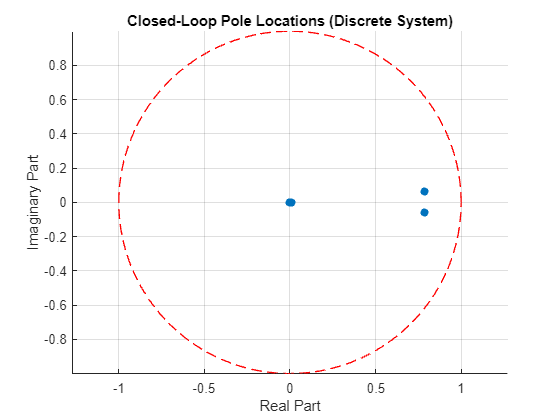


% 폐루프 시스템 행렬
Acl = Ad - Bd * K_d;

% 폐루프 극점 계산
closed_loop_poles = eig(Acl);

% 결과 출력
% disp('Closed-loop poles:');
% disp(closed_loop_poles);

% 극점 시각화
figure;
scatter(real(closed_loop_poles), imag(closed_loop_poles), 'filled');
xlabel('Real Part');
ylabel('Imaginary Part');
title('Closed-Loop Pole Locations (Discrete System)');
grid on;

% 단위원 시각화
hold on;
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), '--r', 'LineWidth', 1); % 단위원
axis equal;

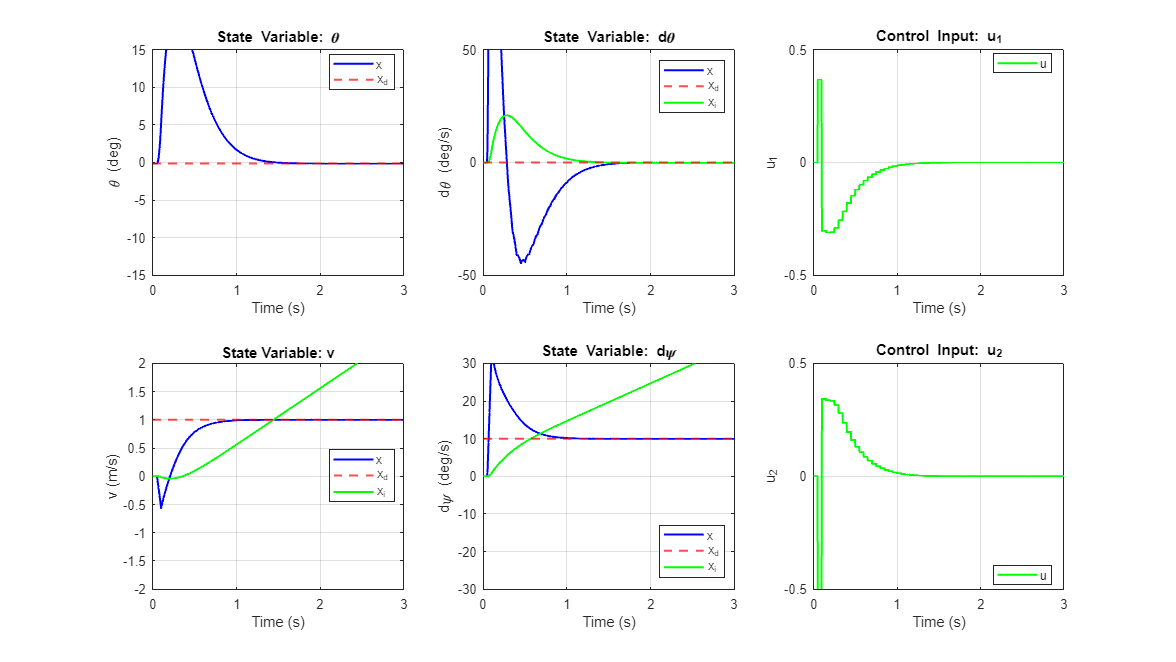




% 초기 설정
x_eq = [theta_eq; 0; 0; 0];
x_next = x_eq + [0; 0; 0; 0];
del_x = zeros(4, 1);

x_d = [theta_eq; 0; 1; 10*pi/180];

xi = zeros(3,1) + [x_next(1);0;0];

u = [0; 0];
x_log = zeros(4, 1);
u_log = zeros(2, 1);
xi_log = zeros(3,1);

% 시뮬레이션
idx = 1;
for t = 0:dt:3
    x = x_next;
    del_x = x - x_eq;
    del_x_d = x_d - x_eq;


    % 시스템 행렬 계산
    M = M_f(I_B_B(1,1),I_B_B(2,1),I_B_B(2,2),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
        I_B_LW(2,1),I_B_LW(2,2),I_B_RW(2,1),I_B_RW(2,2),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3),...
        I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3),L,R,h,m_B,m_LW,m_RW,p_bcom(1),p_bcom(2),p_bcom(3),x(1));

    nle = nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
        I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
        L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), x(4),x(1),x(2),x(3));

    % 샘플링 시간에 따라 입력 업데이트
    if mod(idx, floor(Ts / dt)) == 0
        u = -K_d * (del_x - del_x_d);

        % noise_std = 0.01;
        % noise_mean = 0;
        % % 입력에 노이즈 추가
        % noise = noise_std * randn(size(u)) + noise_mean;
        % u = u + noise;
    end

    % 다음 상태 계산
    x_next = step(x, M, nle, B, u, dt);
    xi = xi + x_next(2:4)*dt;


    % 데이터 저장
    x_log(:, idx) = x;
    u_log(:, idx) = u;
    xi_log(:, idx) = xi;
    idx = idx + 1;
end
% 각도 단위 변환 (rad → deg)
x_log(1:2, :) = x_log(1:2, :) * 180 / pi;
x_log(4, :) = x_log(4, :) * 180 / pi;
x_d(1:2) = x_d(1:2) * 180 / pi;
x_d(4) = x_d(4) * 180 / pi;
xi_log(1,:) = xi_log(1,:) * 180 / pi;
xi_log(3,:) = xi_log(3,:) * 180 / pi;


% 시간 벡터 생성
time = 0:dt:(size(x_log, 2) - 1) * dt;

% 상태 변수 플로팅 (\theta)
figure('units','normalized','outerposition',[0 0 1 1]);
subplot(2,3,1);
plot(time, x_log(1, :), 'b', 'LineWidth', 1.5); hold on;
yline(x_d(1), 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('\theta (deg)');
grid on;
title('State Variable: \theta');
legend('x', 'x_{d}', 'Location', 'best');
ylim([-15, 15]); % Adjust as needed

% 상태 변수 플로팅 (\dot{\theta})
subplot(2,3,2);
plot(time, x_log(2, :), 'b', 'LineWidth', 1.5); hold on;
yline(x_d(2), 'r--', 'LineWidth', 1.5);
plot(time, xi_log(1,:), 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('d\theta (deg/s)');
grid on;
title('State Variable: d\theta');
legend('x', 'x_{d}', 'x_i', 'Location', 'best');
ylim([-50, 50]); % Adjust as needed

% 상태 변수 플로팅 (v)
subplot(2,3,4);
plot(time, x_log(3, :), 'b', 'LineWidth', 1.5); hold on;
yline(x_d(3), 'r--', 'LineWidth', 1.5);
plot(time, xi_log(2,:), 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('v (m/s)');
grid on;
title('State Variable: v');
legend('x', 'x_{d}', 'x_i', 'Location', 'best');
ylim([-2, 2]); % Adjust as needed

% 상태 변수 플로팅 (\dot{\psi})
subplot(2,3,5);
plot(time, x_log(4, :), 'b', 'LineWidth', 1.5); hold on;
yline(x_d(4), 'r--', 'LineWidth', 1.5);
plot(time, xi_log(3,:), 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('d\psi (deg/s)');
grid on;
title('State Variable: d\psi');
legend('x', 'x_{d}', 'x_i', 'Location', 'best');
ylim([-30, 30]); % Adjust as needed

% 입력 변수 플로팅 (u_1)
subplot(2,3,3);
plot(time, u_log(1, :), 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u_1');
grid on;
title('Control Input: u_1');
legend('u', 'Location', 'best');
ylim([-0.5, 0.5]); % Adjust as needed

% 입력 변수 플로팅 (u_2)
subplot(2,3,6);
plot(time, u_log(2, :), 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u_2');
grid on;
title('Control Input: u_2');
legend('u', 'Location', 'best');
ylim([-0.5, 0.5]); % Adjust as needed

% dM_dtheta_finite = M_f(I_B_B(1,1),I_B_B(2,1),I_B_B(2,2),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_LW(2,2),I_B_RW(2,1),I_B_RW(2,2),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3),...
%     I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3),L,R,h,m_B,m_LW,m_RW,p_bcom(1),p_bcom(2),p_bcom(3),theta_eq+epsilon)- ...
%     M_f(I_B_B(1,1),I_B_B(2,1),I_B_B(2,2),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_LW(2,2),I_B_RW(2,1),I_B_RW(2,2),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3),...
%     I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3),L,R,h,m_B,m_LW,m_RW,p_bcom(1),p_bcom(2),p_bcom(3),theta_eq);
% dM_dtheta_finite = dM_dtheta_finite/epsilon
% dnle_dtheta_finite = nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%         I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%         L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq+epsilon,0,0) ...
%         - nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%         I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%         L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq,0,0);
% dnle_dtheta_finite = dnle_dtheta_finite/epsilon
% dnle_dqdot_finite = zeros(3,3);
% dnle_dqdot_finite(:,1) = nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%     L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq,0+epsilon,0) ...
%     - nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%     L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq,0,0);

% dnle_dqdot_finite(:,2) = nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%     L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq,0,0+epsilon) ...
%     - nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%     L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq,0,0);

% dnle_dqdot_finite(:,3) = nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%     L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0+epsilon,theta_eq,0,0) ...
%     - nle_f(I_B_B(1,1),I_B_B(2,1),I_B_B(3,1),I_B_B(3,2),I_B_B(3,3),I_B_LW(1,1),I_B_RW(1,1), ...
%     I_B_LW(2,1),I_B_RW(2,1),I_B_LW(3,1),I_B_LW(3,2),I_B_LW(3,3), I_B_RW(3,1),I_B_RW(3,2),I_B_RW(3,3), ...
%     L,R,g,h,m_B,p_bcom(1),p_bcom(2),p_bcom(3), 0,theta_eq,0,0);

% dnle_dqdot_finite = dnle_dqdot_finite/epsilon

